
% Objective function: Surface area [r, h]
objFun = @(x) pi*x(1)^2 + 2*pi*x(1)*x(2);

% Nonlinear constraint function: Volume >= 1000
nonlcon = @(x) deal(1000 - (pi * x(1)^2 * x(2)), []);

lb = [0.1, 0.1];
ub = [10, 20];
x0 = [5, 10];

options = optimoptions('fmincon', 'Display', 'iter');
[xOpt, fval] = fmincon(objFun, x0, [], [], [], [], lb, ub, nonlcon, options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.926991e+02    2.146e+02    7.292e+00
    1       8    3.746313e+02    2.129e+02    2.187e+00    3.743e+00
    2      11    4.447355e+02    0.000e+00    3.930e+00    7.696e-01
    3      14    4.397375e+02    0.000e+00    2.929e-01    1.736e-01
    4      17    4.393776e+02    0.000e+00    1.560e-02    2.263e-02
    5      20    4.393775e+02    1.407e-04    5.114e-03    3.712e-03
    6      23    4.393776e+02    0.000e+00    9.655e-06    3.029e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 


fprintf('Optimal Radius: %.2f m\nOptimal Height: %.2f m\nMinimum Surface Area: %.2f m^2\n', xOpt(1), xOpt(2), fval);

Optimal Radius: 6.83 m
Optimal Height: 6.83 m
Minimum Surface Area: 439.38 m^2


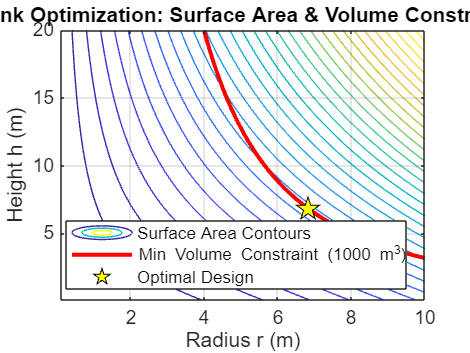


% Plotting Feasible Region & Optimal Point
[R, H] = meshgrid(linspace(0.1, 10, 100), linspace(0.1, 20, 100));
Area = pi.*R.^2 + 2.*pi.*R.*H;
Volume = pi.*R.^2.*H;

figure;
contour(R, H, Area, 30); hold on;
contour(R, H, Volume, [1000 1000], 'LineWidth', 2, 'LineColor', 'r');
plot(xOpt(1), xOpt(2), 'kp', 'MarkerFaceColor', 'y', 'MarkerSize', 12, 'DisplayName', 'Optimal Design');
xlabel('Radius r (m)'); ylabel('Height h (m)');
title('Tank Optimization: Surface Area & Volume Constraint');
legend('Surface Area Contours', 'Min Volume Constraint (1000 m^3)', 'Optimal Design', 'Location', 'best');
grid on;